Electricity Prices (retrieved 9/3/26 @ [Electricity Prices for Netherlands](https://thingler.io/country/Netherlands))

lambda = [12.27 11.2 10.98 11 11.3 11.1 14.09 22.25 24.58 16.49 13.07 10.09 7.62 6.99 7.24 9.13 10.05 12.71 22.34 24.79 21.78 17.06 15.54 13.98];
lambda = lambda / 1000; % cents / Wh
Ts = 900; % 15 minute samples
Nt = 60*60*24/Ts; % Number of samples in a day
Nh = 60*60/Ts; % Number of samples in an hour
lambda = kron(lambda, ones(1,Nt/24)); lambda = lambda./Nh; % divide cost into time steps - cents / W x (15mins)

kb = 1.645e-4; % between floors
kroof = 3.28e-5;
kfacade = 9.67e-5;
C_floor = 387210;

A = [-kb-kfacade kb 0 0;
     kb -kb-kb-kfacade kb 0;
     0 kb -kb-kb-kfacade kb;
     0 0 kb -kb-kfacade-kroof];

Bu_k = zeros(4,3,size(lambda,1)); % state selection, input selection, time step in day
B = zeros(4,4,size(lambda,1));

Bd = [kfacade;
      kfacade;
      kfacade;
      kfacade+kroof];

for i = 1:size(lambda,2)
    Bu_k = [1 0 0;
            0 1 0;
            0 0 1;
            0 0 1] * 1/(lambda(i) * C_floor);
    B(:,:,i) = [Bu_k, Bd];
    if rank(ctrb(A,B(:,:,i))) ~= 4 % check full rank for all B
        disp("NOT FULL RANK AT"+i)
    end
end


C = eye(4); D = zeros(4,4);
tf = ss(A,B,C,D);

% Used to determine sample time (previously)
[y,t] = step(tf(:,:,1));

stepinfo(y(:,1 ,1), t) % ~ 10 steps in rise time

ans = struct with fields:
         RiseTime: 1.6660e+04
    TransientTime: 3.1974e+04
     SettlingTime: 3.1974e+04
      SettlingMin: 4.1488
      SettlingMax: 4.6081
        Overshoot: 0
       Undershoot: 0
             Peak: 4.6081
         PeakTime: 7.8454e+04




tf_d = c2d(tf, Ts, 'zoh');
A = tf_d.A; B = tf_d.B; %B 
A = A(:,:,1); % expands to same size as B but all identical - reduce 

Problem setup

% Parameters
x0 = [23; 1; 50; 18]; 
x_ref = 20; % Desired floor temperature 
Np = 2*Nt; % 2 days
n = size(B,1); 
m = size(B,2);
N_b = size(B,3);


## Stability stuff

% Defining inequality constraints
% Permittable temperature range
a_x1 = eye(n); b_x1 = 30*ones(n,1);
a_x2 = -1*eye(n); b_x2 = zeros(n,1);

% the state constraints are not currently varying in time it would be
% fairly easy to implement that into this bit if we decide that we want a
% varying temperature reference as the day progresses. 

a_x = zeros(8,n,N_b); b_x = zeros(8,1,N_b);
for i = 1:N_b
    a_x(:,:,i) = [a_x1; a_x2]; 
    b_x(:,:,i) = [b_x1; b_x2] - a_x(:,:,i)*x_ref*ones(4,1); % conversion to error coordinates
end

% No negative cost
a_u1 = -eye(m); b_u1 = zeros(m,1);
% Can't exceed 20c per floor in an hour (5c per 15 minutes)
a_u2 = eye(m); b_u2 = 5 * ones(m,1);

a_u = zeros(2*m,n,N_b); b_u = zeros(2*m,1,N_b);

for i = 1:N_b
    a_u(:,:,i) = [a_u1; a_u2]*K(:,:,i);
    b_u(:,:,i) = [b_u1; b_u2]-a_u(:,:,i)*K(:,:,i)*x_ref*ones(4,1);
end


% add some more in plz

a = [a_x ; a_u]; b = [b_x ; b_u];
alpha = determine_worst_case_ellipsoid(a,b,P);
if isempty(nonzeros(alpha))
    disp("Alpha is all zeros");
else
    disp("Alpha is NOT all zeros");
end

Alpha is NOT all zeros



a_x = [a_x1 zeros(n,m);
       a_x2 zeros(n,m)];
b_x = [b_x1; b_x2];
a_u = [zeros(m,n) a_u1;
       zeros(m,n) a_u2];
b_u = [b_u1; b_u2];

% Finding 'desired' steady state cost (see Lec. 5 Slide 6) - I NEED FIXING
% (BUILDING CAPACITY SHIT I ASSUME)
u_ref = zeros(m,N_b);
for i = 1:N_b
    A_u_ref1 = [eye(n)-A -B(:,:,i)]; b_u_ref1 = zeros(4,1);
    A_u_ref2 = [eye(n) zeros(n,m)]; b_u_ref2 = x_ref*ones(m,1);
    temp = linprog([], [A_u_ref1; A_u_ref2; a_x; a_u], [b_u_ref1; b_u_ref2; b_x; b_u]);
    u_ref(:,i) = temp(n+1:end);
end


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal sol

% Quadratic cost element (state)
Qconst = 1;
Q1 = Qconst * diag([1 1 1 1]); 
Q = kron(eye(Np), Q1);

Rconst = 1;
R1 = Rconst * diag([1 1 1 0]);
R = kron(eye(Np), R1);

[P,K] = periodic_riccati(A,B,Q1,R1);

   210




H = [zeros(Np*n, Np*n) zeros(Np*n, Np*m) zeros(Np*n, Np*n);
     zeros(Np*m, Np*n) 2*R zeros(Np*m, Np*n);
     zeros(Np*n, Np*n) zeros(Np*n, Np*m) 2*Q];


% State solution phi
% Extended Controllability matrix
Gamma = zeros(Np*n, Np*m);
for i = 1:Np
    for j = 1:i
        k = mod(i-j+1,N_b)+1;
        Gamma((i-1)*n+1:i*n, (j-1)*m+1:j*m) = A^(i-j)*B(:,:,k); % u_k -> u_k+Np
    end
end
A_phi = [-1*eye(Np*n) Gamma zeros(Np*n)];
% b matrix (A^i X0)
b_phi = zeros(Np*n,1);
for i = 1:Np
    b_phi((i-1)*n+1:i*n) = -A^i*x0;
end

% Defining z = x - x_ref
A_z = [eye(Np*n), zeros(Np*m), -1*eye(Np*n)];
b_z = x_ref * ones(Np*n,1);

% External Temperature
T_ext = 0;
T_ext_IDs = [0 0 0 1];
A_u_ext = [zeros(Np, Np*n) kron(eye(Np), T_ext_IDs) zeros(Np,Np*n)];
b_u_ext = T_ext * ones(Np,1);

% Change between inputs - |u_k+1 - u_k| <= Delta_u
Delta_u = 0.02;
A_uDelta = zeros(Np*(m-1), Np*(m+2*n));
A_template = [1 0 0 0 -1];
for i = 1:m-1
    for j = 1:Np-1
        A_uDelta((j-1)*(m-1)+i, Np*n+(j-1)*(m)+i:Np*n+j*m+i) = A_template;
    end
end
A_uDelta = [A_uDelta; -1*A_uDelta]; % |abc|<= 
b_uDelta = Delta_u * ones(size(A_uDelta,1), 1);

Aineq = [A_uDelta]; Bineq = [b_uDelta];
ub = [100*ones(Np*n,1); 100*ones(Np*m,1)];
lb = [-100*ones(Np*n,1); zeros(Np*m,1)];

Aeq = [A_phi; A_u_ext; A_z];
beq = [b_phi; b_u_ext; b_z];

tic;
run = true;
if run
    [x, fval] = quadprog(H, zeros(1,Np*(n+m+n)), Aineq, Bineq, Aeq, beq, lb, ub);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


time_taken_to_compute = toc; % ~ 2 minutes
T1 = x(1:4:Np*n); 
T2 = x(2:4:Np*n); 
T3 = x(3:4:Np*n); 
T4 = x(4:4:Np*n);
u1 = x(Np*n+1:4:Np*n+Np*m); 
u2 = x(Np*n+2:4:Np*n+Np*m); 
u3 = x(Np*n+3:4:Np*n+Np*m); 
u4 = x(Np*n+4:4:Np*n+Np*m);


Polyhedron

Empty polyhedron in R^0


Plotting data

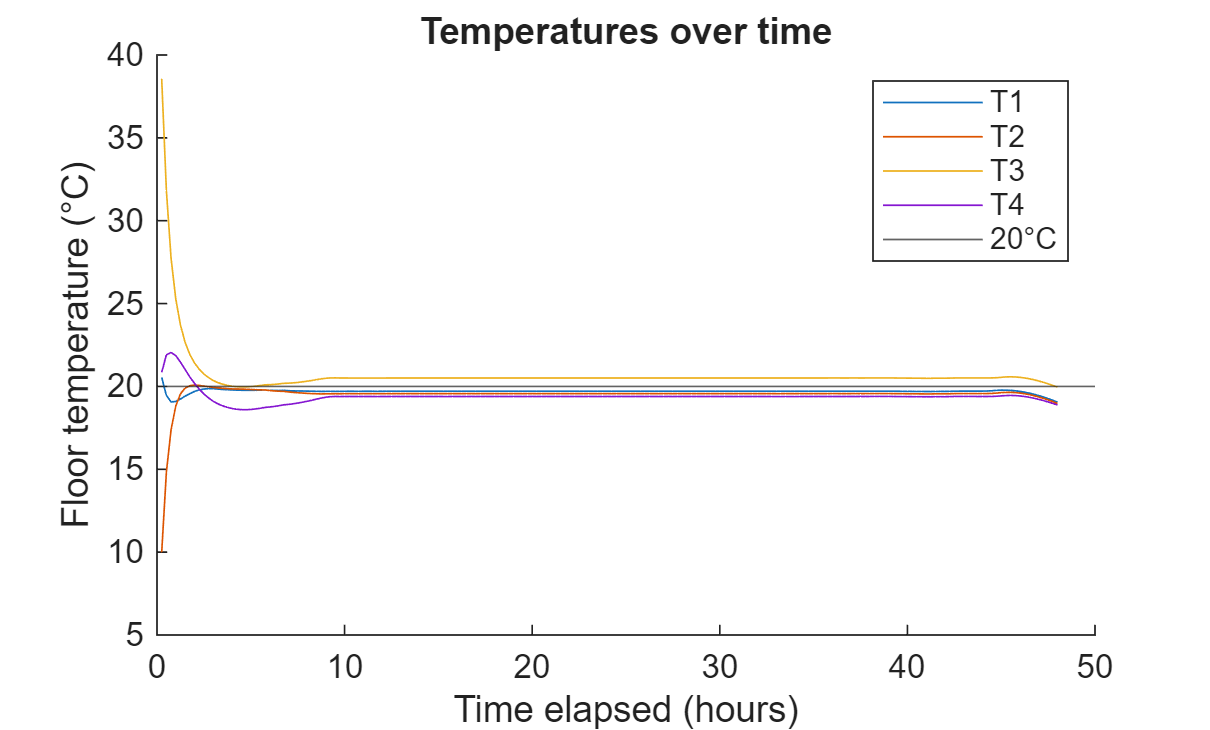

t = (1:Np)/Nh; % time
figure;
hold on
plot(t, T1);
plot(t,T2);
plot(t,T3);
plot(t,T4);
yline(x_ref);
title("Temperatures over time")
legend("T1", "T2", "T3", "T4", x_ref+"°C");
xlabel("Time elapsed (hours)"); ylabel("Floor temperature (°C)")

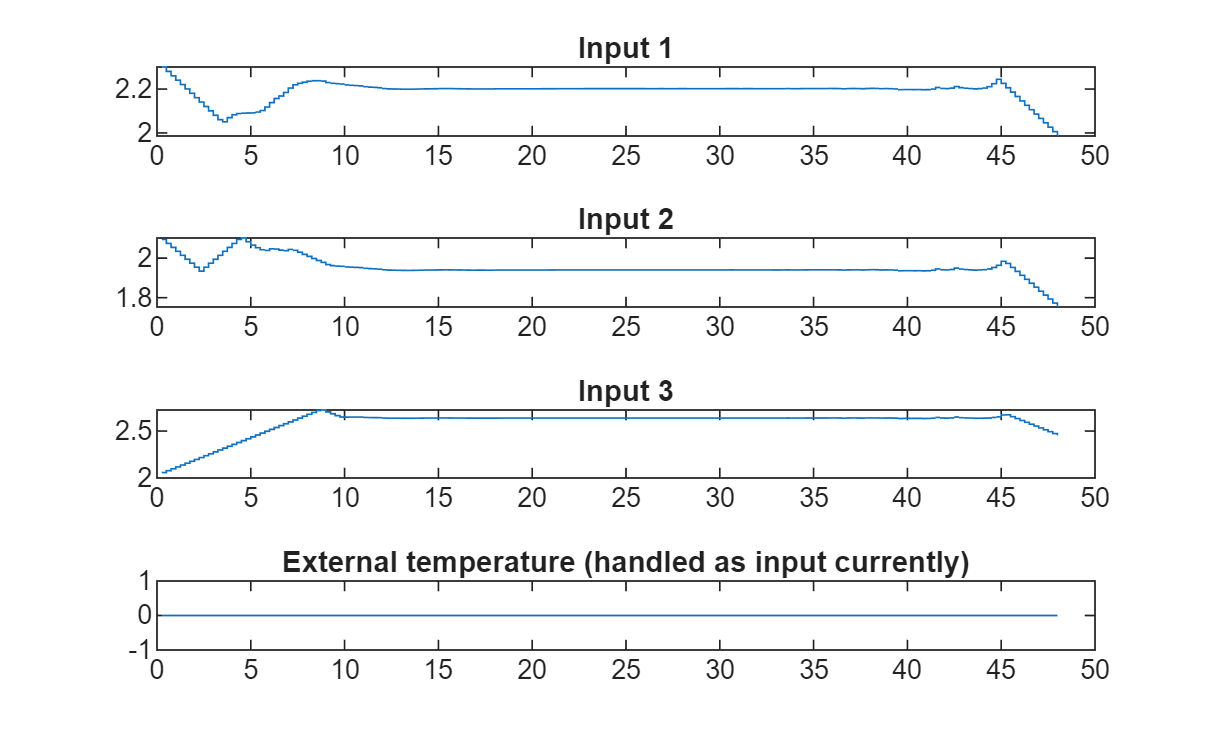


figure;
tiledlayout(4,1);
nexttile
stairs(t,u1);
title("Input 1");
nexttile
stairs(t,u2);
title("Input 2")
nexttile
stairs(t,u3);
title("Input 3")
nexttile
stairs(t,u4);
title("External temperature (handled as input currently)")

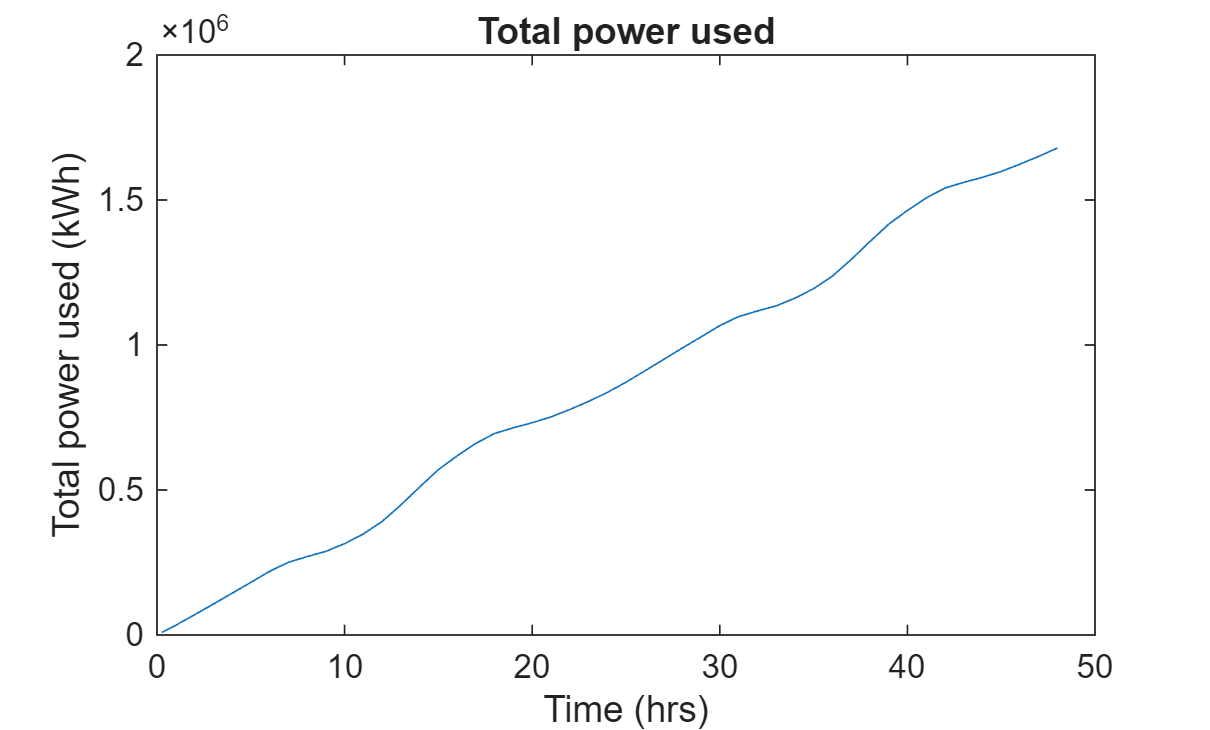


figure;
plot(t,4*cumsum((u1+u2+u3)./kron([1 1],lambda)')) % total kWh - 18000 kWh per day?
title("Total power used")
xlabel("Time (hrs)"); ylabel("Total power used (kWh)");

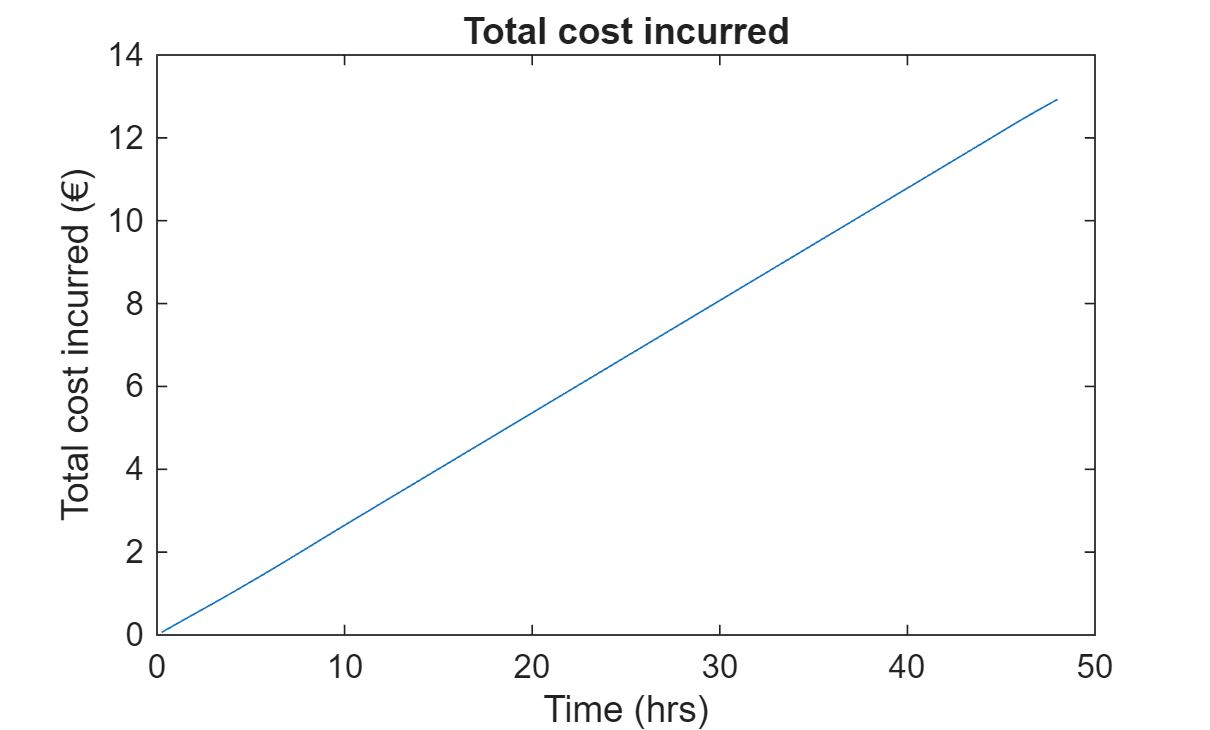


figure;
plot(t, cumsum(u1 + u2 + u3)/100);
title("Total cost incurred");
xlabel("Time (hrs)"); ylabel("Total cost incurred (€)");